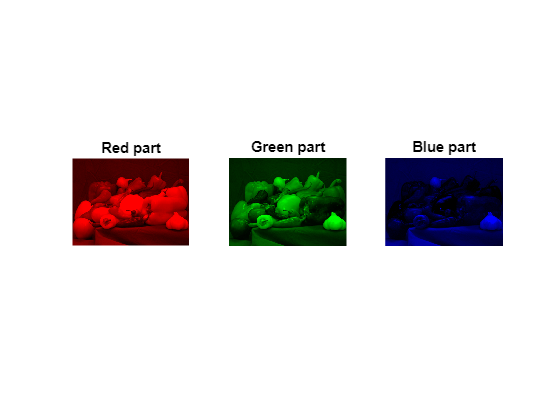

image = imread('peppers.png');
redpart = image(:,:,1);
greenpart = image(:,:,2);
bluepart = image(:,:,3);

redOnlyImage = cat(3, redpart, zeros(size(greenpart)), zeros(size(bluepart)));
greenOnlyImage = cat(3, zeros(size(redpart)), greenpart, zeros(size(bluepart)));
blueOnlyImage = cat(3, zeros(size(redpart)), zeros(size(greenpart)), bluepart);
figure;
subplot(1, 3, 1), imshow(redOnlyImage), title('Red part');
subplot(1, 3, 2), imshow(greenOnlyImage), title('Green part');
subplot(1, 3, 3), imshow(blueOnlyImage), title('Blue part');

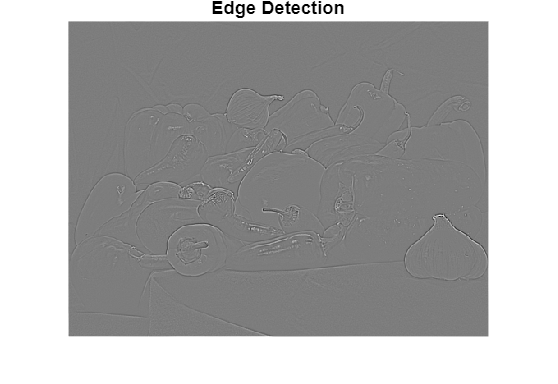

%  Edge detection
edgeKernel = [-1 -1 -1; -1 8 -1; -1 -1 -1];
edgeImage = conv2(double(rgb2gray(image)), edgeKernel, 'same');
figure, imshow(mat2gray(edgeImage)), title('Edge Detection');

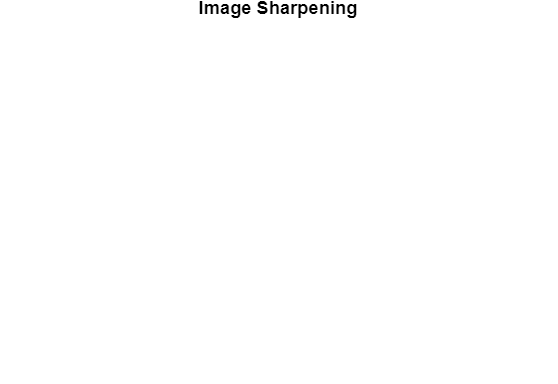


%  Image sharpening
sharpenKernel = [0 -1 0; -1 100 -1; 0 -1 0];
sharpenedImage = conv2(double(rgb2gray(image)), sharpenKernel, 'same');
figure, imshow(mat2gray(sharpenedImage)), title('Image Sharpening');

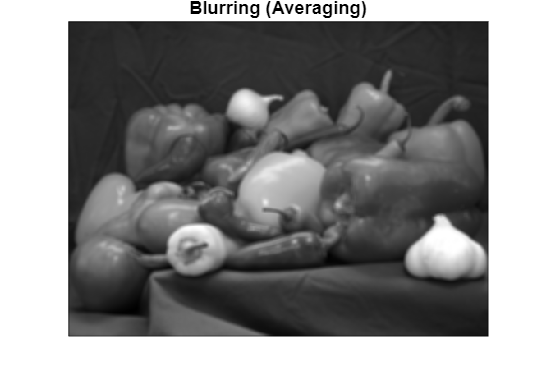


%  Blurring (averaging)
blurKernel = ones(5, 5) / 25;
blurredImage = conv2(double(rgb2gray(image)), blurKernel, 'same');
figure, imshow(mat2gray(blurredImage)), title('Blurring (Averaging)');

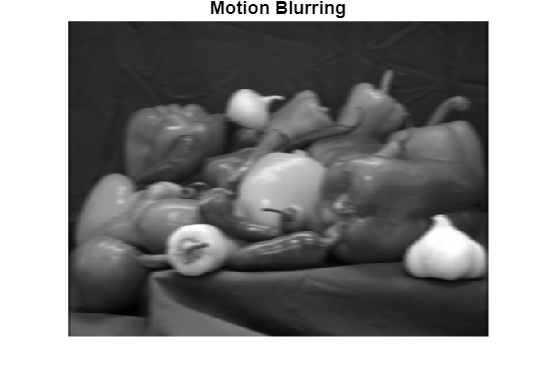


%  Motion blurring
motionBlurKernel = zeros(9, 9);
motionBlurKernel(5,:) = 1/9;
motionBlurredImage = conv2(double(rgb2gray(image)), motionBlurKernel, 'same');
figure, imshow(mat2gray(motionBlurredImage)), title('Motion Blurring'); motionBlurKernel_freq = fft2(motionBlurKernel, size(image,1), size(image,2));

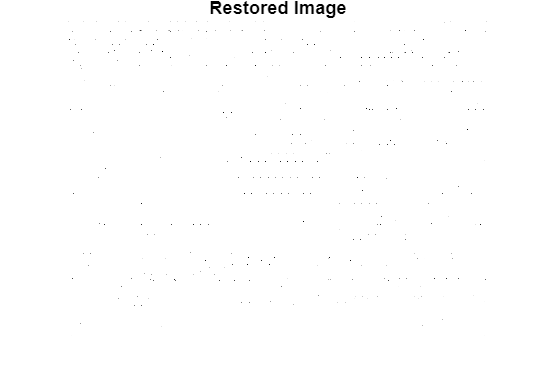

image_freq = fft2(double(redpart));

% Restore image in frequency domain
restored_image_freq = image_freq ./ motionBlurKernel_freq;

% Inverse FFT to get the restored image
restored_image = ifft2(restored_image_freq);

% Display and save the restored image
figure;
imshow(abs(restored_image)/255), title('Restored Image');

imwrite(uint8(abs(restored_image)),'image5.png');